plan path between two states 

ss=stateSpaceSE2;
sv=validatorOccupancyMap(ss);

load example map and set map resolution as 10 cells/meter

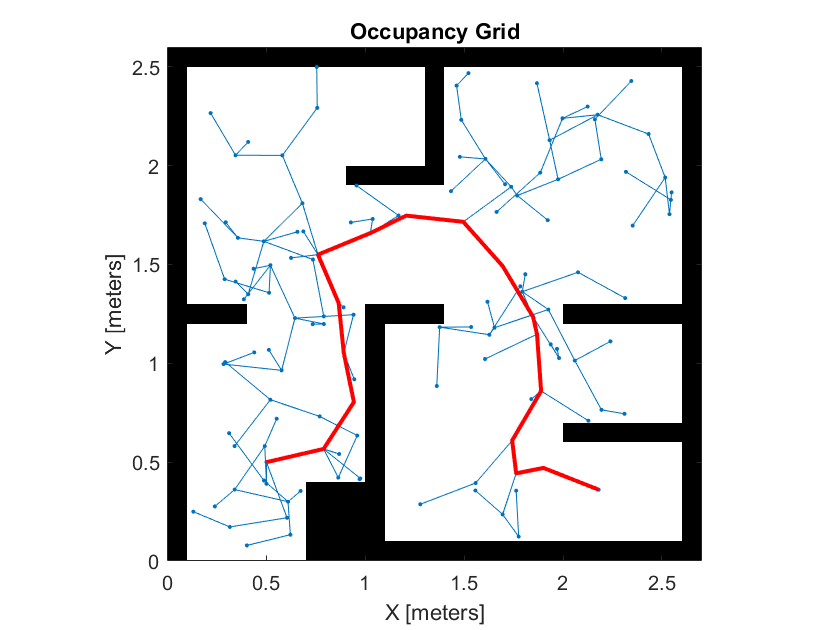

load exampleMaps
map=occupancyMap(simpleMap,10);
sv.Map=map;
sv.ValidationDistance = 0.01;
ss.StateBounds = [map.XWorldLimits;map.YWorldLimits; [-pi pi]];
planner = plannerRRT(ss,sv);
planner.MaxConnectionDistance = 0.3;
start = [0.5,0.5,0];
goal = [2.5,0.2,0];
rng(100,'twister'); % for repeatable result
[pthObj,solnInfo] = plan(planner,start,goal);
show(map)
hold on
plot(solnInfo.TreeData(:,1),solnInfo.TreeData(:,2),'.-'); % tree expansion
plot(pthObj.States(:,1),pthObj.States(:,2),'r-','LineWidth',2) % draw path